load('/Users/platel/Desktop/exp/aurelie/tablebrainbow.mat')

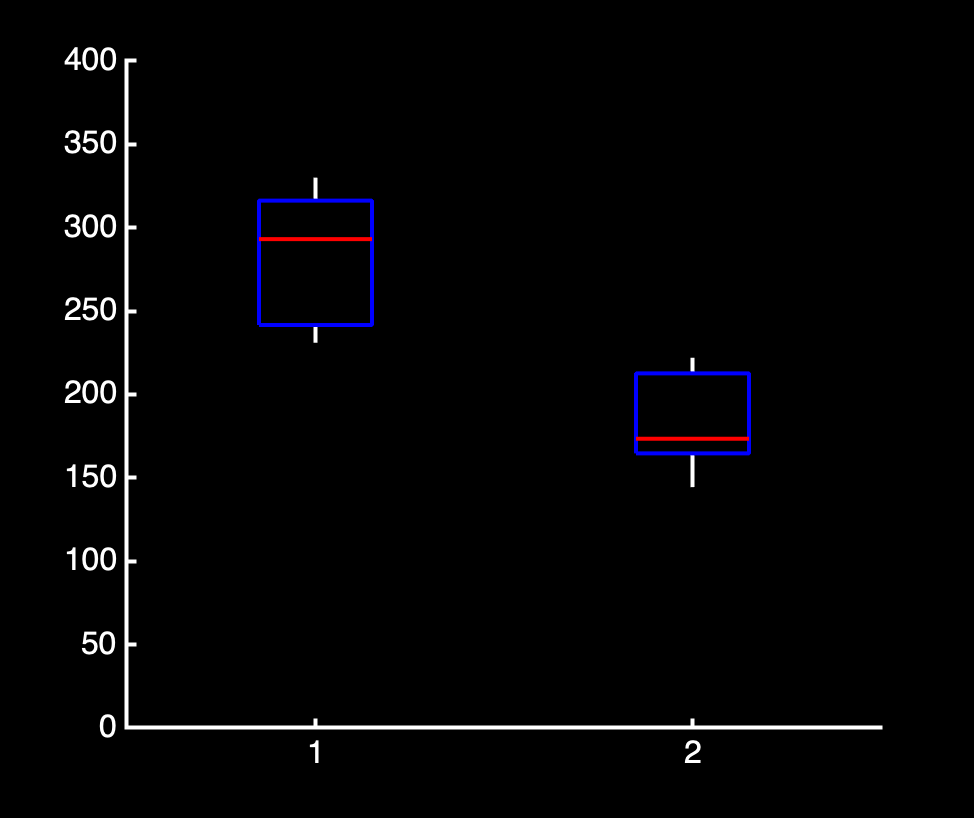

%size assembly
meandistance_assemblies=table2array(analysisbrainbowALL20Dec(2:end,6));
meandistance_allcells=table2array(analysisbrainbowALL20Dec(2:end,8));
fig=boxplot([meandistance_allcells meandistance_assemblies]);

set(gca,'FontSize',16,'TickLabelInterpreter','none','XTick',[1 2],...
    'XTickLabel',{'1','2'});
h=findobj('LineStyle','-'); set(h,'LineWidth',2);%set(h,'Color','w')
h=findobj('LineStyle','--'); set(h, 'LineStyle','-');set(h,'LineWidth',2);set(h,'Color','w')

box off
ylim([0, 400]);
ax = gca;

% Set the linewidth of the x-axis and y-axis
ax.XAxis.LineWidth = 2; % Change '2' to your desired linewidth
ax.YAxis.LineWidth = 2; % Change '2' to your desired linewidth
ax.XAxis.Color='w';
ax.YAxis.Color='w';
fig=gcf;
currentPosition = fig.Position;
fig.Position = [currentPosition(1), currentPosition(2), 500, currentPosition(4)];
set(fig, 'Color', 'k'); % Set the figure background color to black
set(gca, 'Color', 'k'); % Set the axis background color to black


% h=findobj('Marker','+'); set(h, 'Marker','o'); set(h,'MarkerFaceColor','r');
% set(fig, 'Color', 'k'); % Set the figure background color to black
% 
% % ax = axes('Parent', fig);
% set(gca, 'Color', 'k'); % Set the axis background color to black


% hold on
% % scatter(1,meandistance_allcells)
% % scatter(2,meandistance_assemblies)
% hold off

% h=findobj('LineStyle','--'); set(h, 'LineStyle','-');
% h=findobj('Marker','+'); set(h, 'Marker','o'); set(h,'MarkerFaceColor','r')
% %axis ij
% %axis tight
% set(h,'MarkerFaceColor','r')
% set(ax, 'XColor', 'w');
% set(ax, 'YColor', 'w');
% set(ax, 'Color', 'k');

% Number assemblies 
mean_assemblies=table2array(analysisbrainbowALL20Dec(2:end,4));
mean_assemblies_colored=table2array(analysisbrainbowALL20Dec(2:end,10));
mean(mean_assemblies)

ans = 4.9571

mean(mean_assemblies_colored)

ans = 1.5143


fig=boxplot([mean_assemblies mean_assemblies_colored]);
set(gca,'FontSize',16,'TickLabelInterpreter','none','XTick',[1 2],...
    'XTickLabel',{'1','2'});
h=findobj('LineStyle','-'); set(h, 'LineStyle','-');set(h,'LineWidth',2);%set(h,'Color','w')
h=findobj('LineStyle','--'); set(h, 'LineStyle','-');set(h,'LineWidth',2);set(h,'Color','w')
h=findobj('Marker','+'); set(h, 'Marker','o'); set(h,'MarkerEdgeColor','k')
box off
ylim([0, 10]);
ax = gca;

% Set the linewidth of the x-axis and y-axis
ax.XAxis.LineWidth = 2; % Change '2' to your desired linewidth
ax.YAxis.LineWidth = 2; % Change '2' to your desired linewidth
ax.XAxis.Color='w';
ax.YAxis.Color='w';
fig=gcf;
currentPosition = fig.Position;
fig.Position = [currentPosition(1), currentPosition(2), 500, currentPosition(4)];
set(fig, 'Color', 'k'); % Set the figure background color to black
set(gca, 'Color', 'k'); % Set the axis background color to black


% fig = figure('visible','off');
figure
colormap ("gray")
imagesc(calcium)
% title ('all cells','Position', [0, 1.3, 0],'FontSize',16);
hold on

%for n=transpose(cell2mat(assembly(num)))
for n=1:NCell

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='black';
    end

    x=cell2mat(outline_gcampx(n));
    y=cell2mat(outline_gcampy(n));
    sorted_indices = convhull(x, y); 
    x = x(sorted_indices);
    y = y(sorted_indices);
    % patch(x, y,col,'FaceAlpha', 1,'EdgeColor','k','LineWidth',1)
    % patch(x, y,col,'FaceAlpha', 0,'EdgeColor','w','LineWidth',1)
    % text(max(x),max(y),num2str(n),"FontSize",8,"Color",'w')
    plot(x, y, '.', 'MarkerSize', 4,"Color",'w');
    axis off
    axis image
        

end

% namegraph=strcat(namefull,['allcells' , '.png']);
% if isfolder(namefull)
%     exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')
%     close gcf
% end